# ENOB over Temperature Identification

测试目的：利用热风枪改变芯片温度，利用热敏电阻反应温度变化，在变温的同时，不停地进行Calibration & A/D Conversion，从而绘制ENOB over Temperature的曲线；

clear
clc

N_Temp = 12;
N_Cycle = 10;
sinad_flash = zeros(N_Temp, N_Cycle);
thd_flash = zeros(N_Temp, N_Cycle);
sinad_const_gain = zeros(N_Temp, N_Cycle);
thd_const_gain = zeros(N_Temp, N_Cycle);
ORI_SINAD = zeros(N_Temp, N_Cycle);
ORI_THD = zeros(N_Temp, N_Cycle);
MAX_SINAD = zeros(N_Temp, N_Cycle);
MAX_SINAD_GAIN = zeros(N_Temp, N_Cycle);
MAX_THD = zeros(N_Temp, N_Cycle);
MAX_THD_GAIN = zeros(N_Temp, N_Cycle);
Vamp = zeros(N_Temp, N_Cycle);
Vamp_const_gain = zeros(N_Temp, N_Cycle);
command_prefix = ["sinad_flash", "thd_flash", "sinad_const_gain", ...
        "thd_const_gain", "ORI_SINAD", "ORI_THD", ...
        "Vamp", "Vamp_const_gain"];

### Data Process of each Cycle

filename_prefix = "./data/TemperatureResults_";
CONST_GAIN = 15.2746;
tic
for i = 1:N_Temp
    for j = 1:N_Cycle
        fprintf("Temperature [%d/%d]    Cycle [%d/%d]\n", i, N_Temp, j, N_Cycle);
        filename = strcat(filename_prefix, ...
            num2str(i), '_', num2str(j), '.mat');
        Cycle = Cycle_Process_2(filename, CONST_GAIN);
        for k = 1:length(command_prefix)
            command = strcat(command_prefix(k), "(i,j)=Cycle.", command_prefix(k),";");
            eval(command)
        end
        MAX_SINAD(i,j) = Cycle.MAX_SINAD(1);
        MAX_SINAD_GAIN(i,j) = Cycle.MAX_SINAD(2);
        MAX_THD(i,j) = Cycle.MAX_THD(1);
        MAX_THD_GAIN(i,j) = Cycle.MAX_THD(2);
    end
end

Temperature [1/12]    Cycle [1/10]


Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 6).


Temperature [1/12]    Cycle [2/10]
Temperature [1/12]    Cycle [3/10]
Temperature [1/12]    Cycle [4/10]
Temperature [1/12]    Cycle [5/10]
Temperature [1/12]    Cycle [6/10]
Temperature [1/12]    Cycle [7/10]
Temperature [1/12]    Cycle [8/10]
Temperature [1/12]    Cycle [9/10]
Temperature [1/12]    Cycle [10/10]
Temperature [2/12]    Cycle [1/10]
Temperature [2/12]    Cycle [2/10]
Temperature [2/12]    Cycle [3/10]
Temperature [2/12]    Cycle [4/10]
Temperature [2/12]    Cycle [5/10]
Temperature [2/12]    Cycle [6/10]
Temperature [2/12]    Cycle [7/10]
Temperature [2/12]    Cycle [8/10]
Temperature [2/12]    Cycle [9/10]
Temperature [2/12]    Cycle [10/10]
Temperature [3/12]    Cycle [1/10]
Temperature [3/12]    Cycle [2/10]
Temperature [3/12]    Cycle [3/10]
Temperature [3/12]    Cycle [4/10]
Temperature [3/12]    Cycle [5/10]
Temperature [3/12]    Cycle [6/10]
Temperature [3/12]    Cycle [7/10]
Temperature [3/12]    Cycle [8/10]
Temperature [3/12]    Cycle [9/10]
Temperature [3/12]

toc

历时 697.927383 秒。


## Loading Temperature_fit.csv

result = readtable("Temperature_fit.csv", 'VariableNamingRule','preserve')

result = 120×7 table
    Prefix_index    Cycle_index     Gain     SINAD with Calibration    THD with Calibration    SINAD without Calibration    THD without Calibration
    ____________    ___________    ______    ______________________    ____________________    _________________________    _______________________

         1               1         15.271            80.52                    -94.56                     62.37                       -70.4         
         1               2         15.278            80.88                    -94.66                     62.45                      -70.54         
         1               3         15.276            80.87                    -94.09                     62.39                      -70.27         
         1               4         15.275            80.71                    -94.42                      62.4                      -70.47         
         1               5         15.276            81.02                    -94.66      

gain_list = reshape(result.("Gain"), [N_Cycle, N_Temp]);
Gain_mean_list = mean(gain_list)

Gain_mean_list =    15.2746   15.2656   15.2690   15.2564   15.2459   15.2273   15.2175   15.1959   15.1783   15.1653   15.1269   15.1273


## Plot Results and Compare

Temp = [30 35 40 50 60 70 80 90 100 110 120 130]

Temp =     30    35    40    50    60    70    80    90   100   110   120   130


mean_prefix = ["sinad_flash", "thd_flash", "sinad_const_gain", ...
        "thd_const_gain", "ORI_SINAD", "ORI_THD", ...
        "MAX_SINAD", "MAX_SINAD_GAIN", "MAX_THD", "MAX_THD_GAIN", ...
        "Vamp", "Vamp_const_gain"];
for k = 1:length(mean_prefix)
    command = strcat(mean_prefix(k), "_mean=mean(", mean_prefix(k),",2);");
    eval(command)
end


#### Specification of Flash ADC

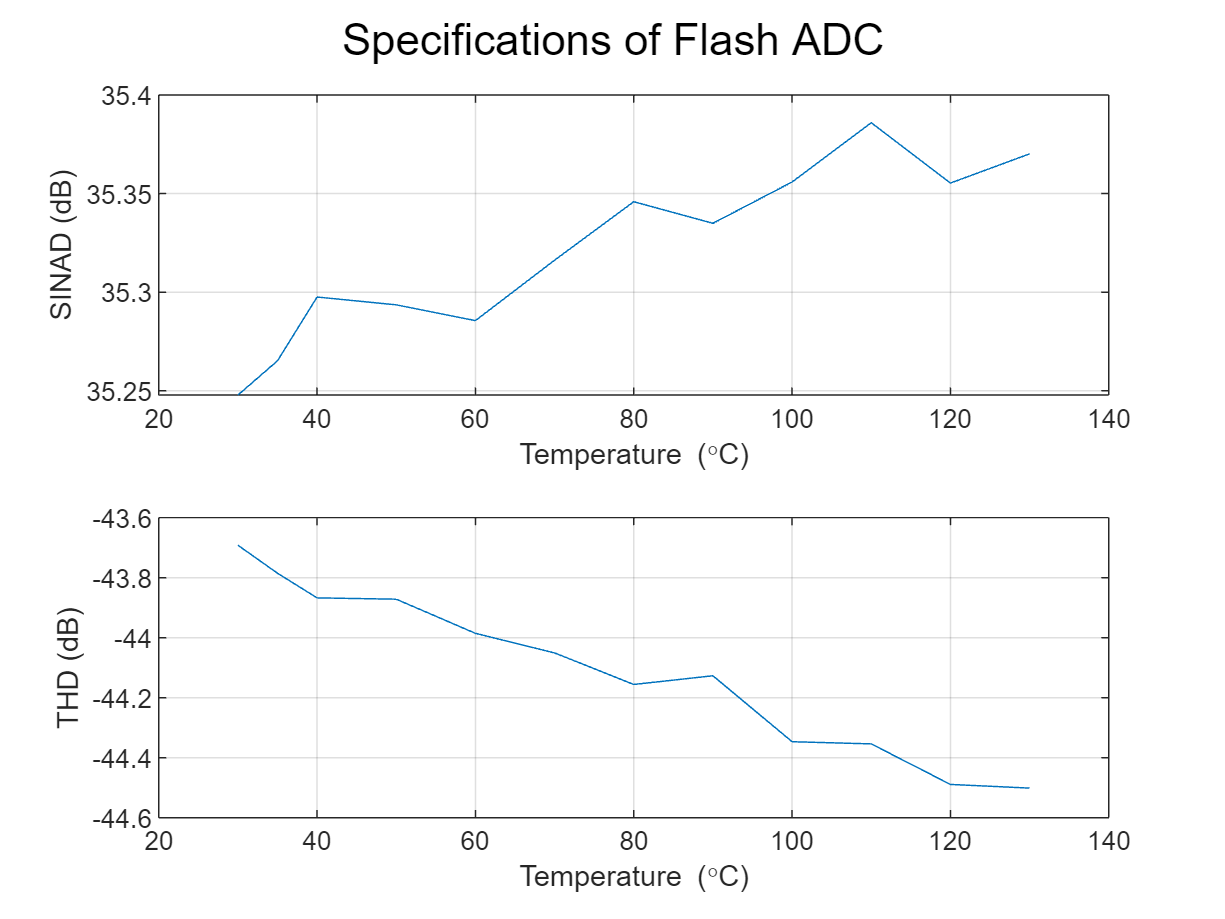

figure
subplot(211)
plot(Temp, sinad_flash_mean);
grid on;
xlabel('Temperature (\circC)');
ylabel('SINAD (dB)');
subplot(212)
plot(Temp, thd_flash_mean);
xlabel('Temperature (\circC)');
ylabel('THD (dB)');
grid on;
sgtitle("Specifications of Flash ADC")

#### Specification of Gain Calibration

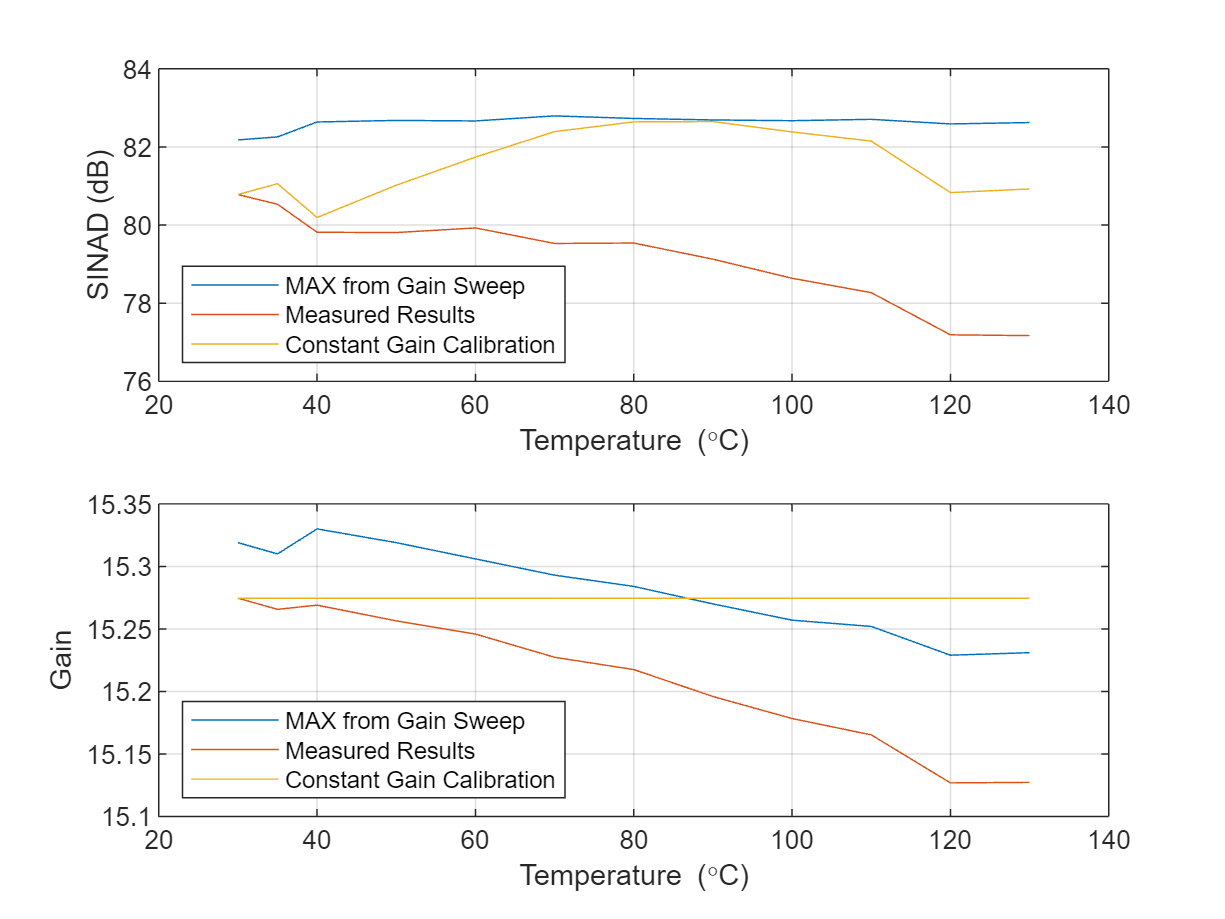

figure
subplot(211)
plot(Temp, [MAX_SINAD_mean, sinad_const_gain_mean]);
grid on;
xlabel('Temperature (\circC)');
ylabel('SINAD (dB)');
legend(["MAX from Gain Sweep", "Constant Gain Calibration"], 'Location','southwest')
subplot(212)
plot(Temp, [MAX_SINAD_GAIN_mean, Gain_mean_list', ones([N_Temp,1])*CONST_GAIN]);
xlabel('Temperature (\circC)');
ylabel('Gain');
legend(["MAX from Gain Sweep", "Measured Results", "Constant Gain Calibration"], 'Location','southwest')
grid on;

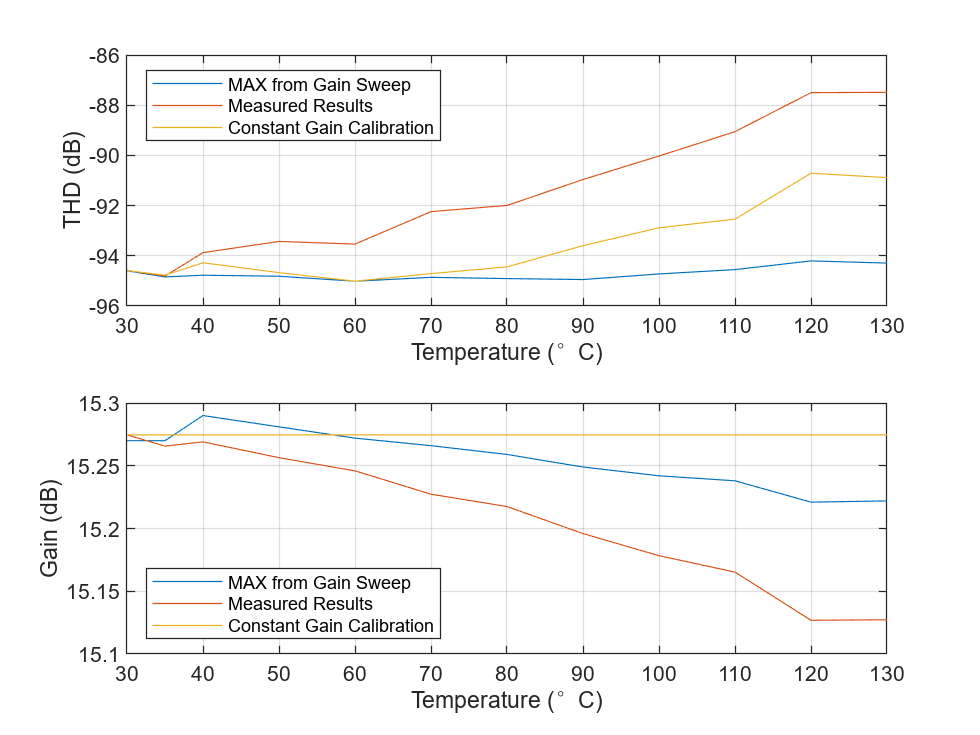


figure
subplot(211)
plot(Temp, [MAX_THD_mean, ORI_THD_mean, thd_const_gain_mean]);
grid on;
xlabel('Temperature (\circC)');
ylabel('THD (dB)');
legend(["MAX from Gain Sweep", "Measured Results", "Constant Gain Calibration"], 'Location','northwest')
subplot(212)
plot(Temp, [MAX_THD_GAIN_mean, Gain_mean_list', ones([N_Temp,1])*CONST_GAIN]);
xlabel('Temperature (\circC)');
ylabel('Gain (dB)');
legend(["MAX from Gain Sweep", "Measured Results", "Constant Gain Calibration"], 'Location','southwest')
grid on;

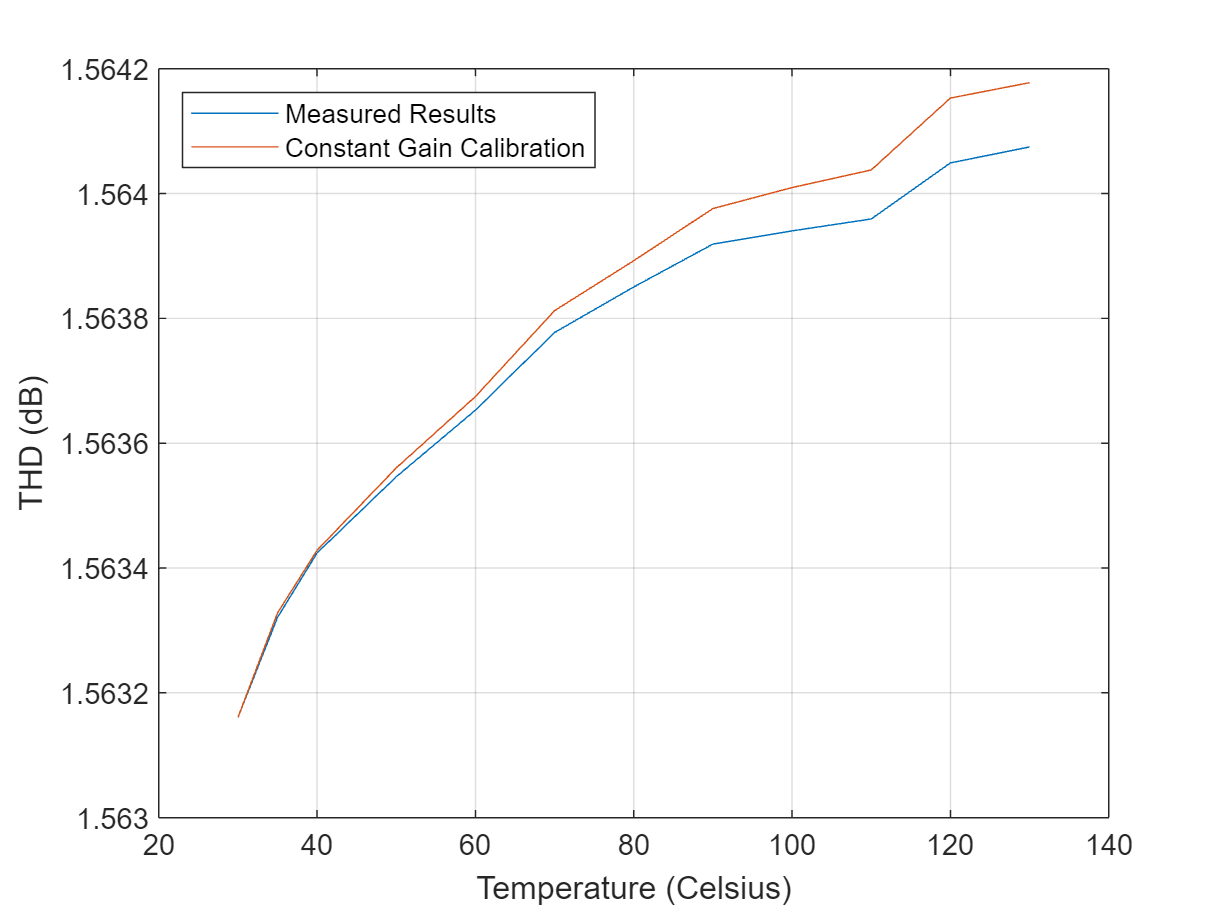

figure
plot(Temp, [Vamp_mean, Vamp_const_gain_mean]);
grid on;
xlabel('Temperature (Celsius)');
ylabel('THD (dB)');
legend(["Measured Results", "Constant Gain Calibration"], 'Location','northwest')

mag2db(1.8 ./ Vamp_const_gain_mean)'

ans =     1.2254    1.2244    1.2239    1.2232    1.2225    1.2218    1.2213    1.2208    1.2207    1.2205    1.2199    1.2197


mag2db(1.8 ./ Vamp_mean)'

ans =     1.2254    1.2245    1.2239    1.2232    1.2226    1.2220    1.2215    1.2212    1.2210    1.2209    1.2204    1.2203


clean_prefix = ["sinad_const_gain_mean", "thd_const_gain_mean", "Gain_mean_list", ...
        "MAX_SINAD_mean", "MAX_SINAD_GAIN_mean", "MAX_THD_mean", "MAX_THD_GAIN_mean", ...
        "Vamp_mean", "Vamp_const_gain_mean", "Temp"];
for k = 1:length(clean_prefix)
    command = strcat(clean_prefix(k), "(2) = [];");             %   clean 35 Celsius
    eval(command)
    command = strcat(clean_prefix(k), "(end) = [];");           %   clean 130 Celsius
    eval(command)
end


## Display Results

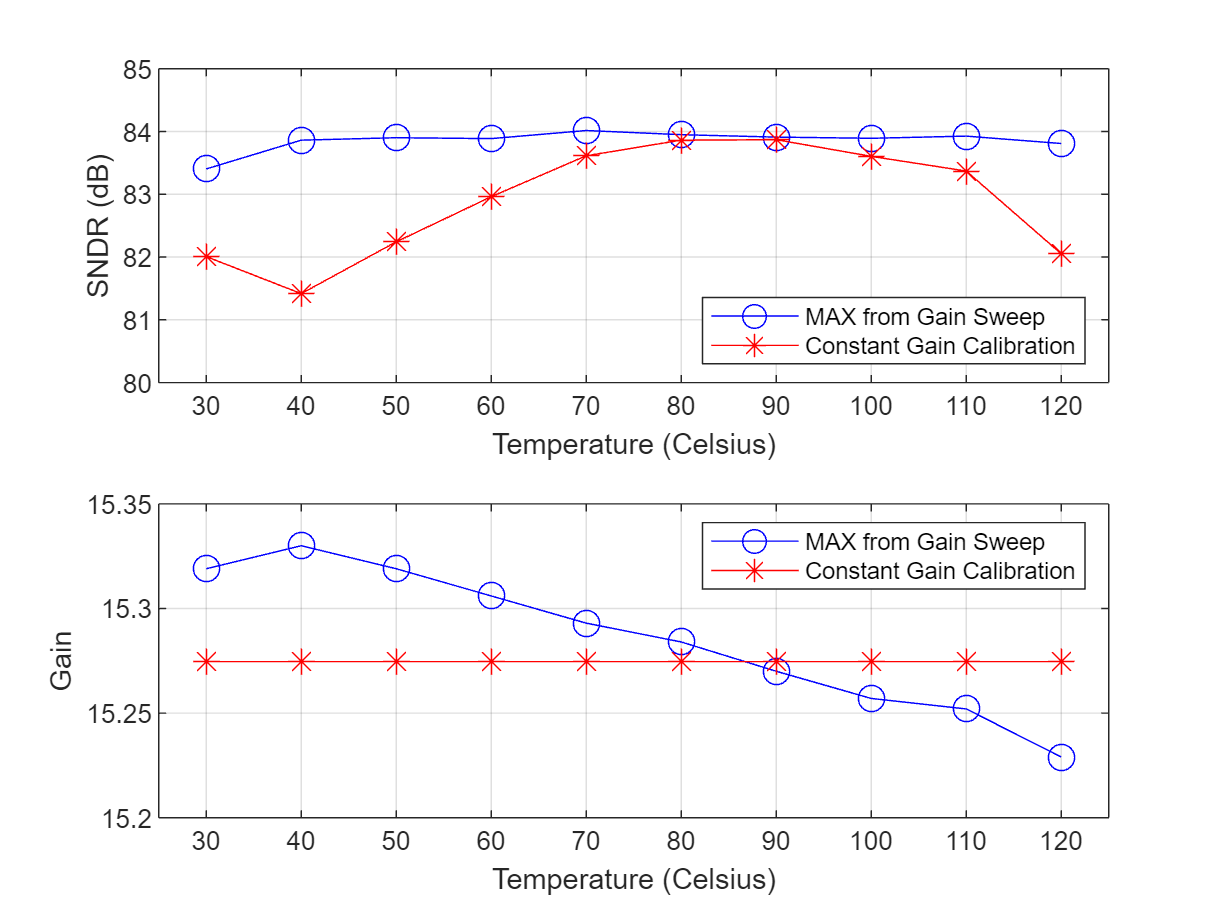

Vamp_added = mag2db(1.8 ./ Vamp_mean);

figure("Name", "SNDR")
subplot(211)
plot(Temp, (MAX_SINAD_mean+Vamp_added), "Color",[0 0 1],'Marker','o','MarkerSize',9);
hold on;
plot(Temp, sinad_const_gain_mean+Vamp_added, "Color", [1 0 0], 'Marker','*','MarkerSize',9);
grid on;
hold off;
xlim([25 125])
ylim([80 85])
xlabel('Temperature (Celsius)');
ylabel('SNDR (dB)');
legend(["MAX from Gain Sweep", "Constant Gain Calibration"], 'Location','southeast')

subplot(212)
plot(Temp, MAX_SINAD_GAIN_mean, "Color",[0 0 1], 'Marker','o','MarkerSize',9);
hold on;
plot(Temp, CONST_GAIN*ones(1, 10), "Color", [1 0 0], 'Marker','*','MarkerSize',9);
grid on;
hold off;
xlim([25 125])
ylim([15.2 15.35])
xlabel('Temperature (Celsius)');
ylabel('Gain');
legend(["MAX from Gain Sweep", "Constant Gain Calibration"], 'Location','northeast')
grid on;

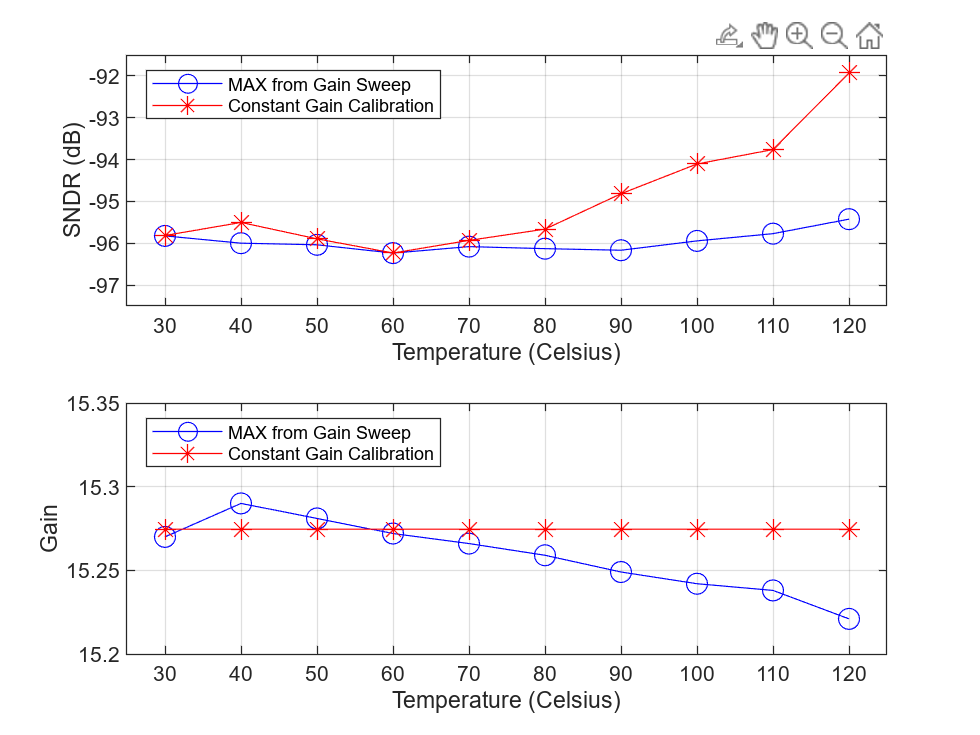

figure("Name", "THD")
subplot(211)
plot(Temp, (MAX_THD_mean-Vamp_added), "Color",[0 0 1],'Marker','o','MarkerSize',9);
hold on;
plot(Temp, thd_const_gain_mean-Vamp_added, "Color", [1 0 0], 'Marker','*','MarkerSize',9);
grid on;
hold off;
xlim([25 125])
ylim([-97.5 -91.5])
xlabel('Temperature (Celsius)');
ylabel('SNDR (dB)');
legend(["MAX from Gain Sweep", "Constant Gain Calibration"], 'Location','northwest')

subplot(212)
plot(Temp, MAX_THD_GAIN_mean, "Color",[0 0 1], 'Marker','o','MarkerSize',9);
hold on;
plot(Temp, CONST_GAIN*ones(1, 10), "Color", [1 0 0], 'Marker','*','MarkerSize',9);
grid on;
hold off;
xlim([25 125])
ylim([15.2 15.35])
xlabel('Temperature (Celsius)');
ylabel('Gain');
legend(["MAX from Gain Sweep", "Constant Gain Calibration"], 'Location','northwest')
grid on;